# Práctica 10: Transformada de FourierDiscreta.

clear all; clc; close all;

1. Utilice la funcion dftmtx() de Matlab para determinar la matriz de factores de fase de la DFT de 4 y 8 puntos.

W4 = dftmtx(4);
W4 = sym(W4)

$$W4 = \left(\begin{array}{cccc} 1 & 1 & 1 & 1\\ 1 & -\mathrm{i} & -1 & \mathrm{i}\\ 1 & -1 & 1 & -1\\ 1 & \mathrm{i} & -1 & -\mathrm{i} \end{array}\right)$$

W8 = dftmtx(8);
W8 = sym(W8)

$$W8 = \begin{array}{l} \left(\begin{array}{cccccccc} 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1\\ 1 & \sigma_{3} & -\mathrm{i} & \sigma_{1} & -1 & \sigma_{2} & \mathrm{i} & \sigma_{4}\\ 1 & -\mathrm{i} & -1 & \mathrm{i} & 1 & -\mathrm{i} & -1 & \mathrm{i}\\ 1 & \sigma_{1} & \mathrm{i} & \sigma_{3} & -1 & \sigma_{4} & -\mathrm{i} & \sigma_{2}\\ 1 & -1 & 1 & -1 & 1 & -1 & 1 & -1\\ 1 & \sigma_{2} & -\mathrm{i} & \sigma_{4} & -1 & \sigma_{3} & \mathrm{i} & \sigma_{1}\\ 1 & \mathrm{i} & -1 & -\mathrm{i} & 1 & \mathrm{i} & -1 & -\mathrm{i}\\ 1 & \sigma_{4} & \mathrm{i} & \sigma_{2} & -1 & \sigma_{1} & -\mathrm{i} & \sigma_{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{2}\,\left(-\frac{1}{2}-\frac{1}{2}\,\mathrm{i}\right)\\ \sigma_{2}=\sqrt{2}\,\left(-\frac{1}{2}+\frac{1}{2}\,\mathrm{i}\right)\\ \sigma_{3}=\sqrt{2}\,\left(\frac{1}{2}-\frac{1}{2}\,\mathrm{i}\right)\\ \sigma_{4}=\sqrt{2}\,\left(\frac{1}{2}+\frac{1}{2}\,\mathrm{i}\right) \end{array}$$

2. Calcule la DFT de 4 puntos de la secuencia de x(n) = {1,2,3,4} mediante la multiplicacion de factores de 4 puntos de W4 y el vector x formado por las muestras x(n). Represente graficamente el espectro discreto de magnitud |X(k)| utilizando la funcion stem().

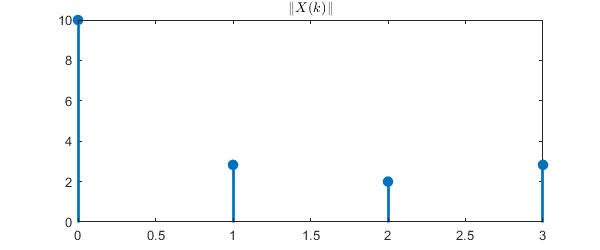

figure('Position',[500 400 600 250])
W4 = dftmtx(4);
x = [1;2;3;4];
X = W4*x;
stem([0:3],abs(X),'filled','LineWidth',2)  
title('$\|X(k)\|$','Interpreter','latex')

3. Calcule la DFT de 8 puntos de la secuencia de x(n) = {1,2,3,4,4,3,2,1} mediante la multiplicacion de factores de 8 puntos de W8 y el vector x formado por las muestras x(n). Represente graficamente el espectro discreto de magnitud |X(k)| utilizando la funcion stem().

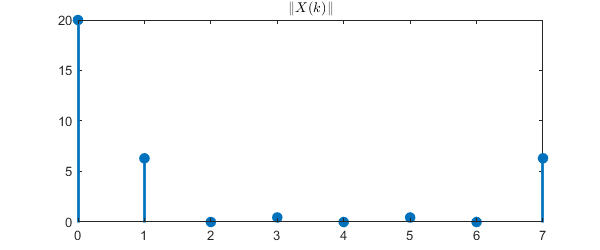

figure('Position',[500 400 600 250])
W8 = dftmtx(8);
x = [1;2;3;4;4;3;2;1];
X = W8*x;
stem([0:7],abs(X),'filled','LineWidth',2)  
title('$\|X(k)\|$','Interpreter','latex')

4. Utilice la función fft() de Matlab para calcular la transformada de Fourier discreta de 64 puntos de la función 𝑥(𝑛)=𝛿(𝑛). Represente gráficamente el espectro de magnitud |𝑋(𝑘)| utilizando la función stem().

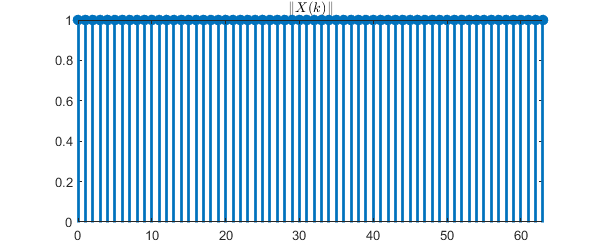

impulso = @(n) n==0;
n = 0:63;
x = impulso(n);
X = fft(x);
stem([0:63],X,'filled','LineWidth',2)
xlim([0 63])
title('$\|X(k)\|$','Interpreter','latex')

5. Utilice la función fft() de Matlab para calcular la transformada de Fourier discreta de 128 puntos de un pulso rectangular de longitud 8. Represente gráficamente el espectro de magnitud |𝑋(𝑘)| utilizando la función stem().

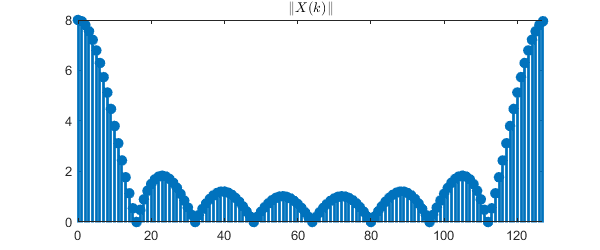

escalon = @(n) n>=0;
n = 0:7;
x = escalon(n)-escalon(n-8);
X = fft(x,128);
stem([0:127],abs(X),'filled','LineWidth',2)
xlim([0 127])
title('$\|X(k)\|$','Interpreter','latex')

6. Utilice la función fft() de Matlab para calcular la transformada de Fourier discreta de 128 puntos de las secuencias 𝑥1(𝑛)=cos(40𝜋𝑛/128) y 𝑥2(𝑛)=𝑐𝑜𝑠(39𝜋𝑛/128).  Represente  gráficamente el espectro de magnitud |𝑋(𝑘)| utilizando la función stem().

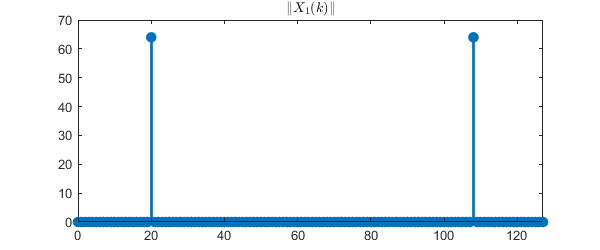

n = 0:127;
x1 = cos(40*pi*n/128);
x2 = cos(39*pi*n/128);
X1 = fft(x1);
X2 = fft(x2);
stem([0:127],abs(X1),'filled','LineWidth',2)
xlim([0 127])
title('$\|X_{1}(k)\|$','Interpreter','latex')

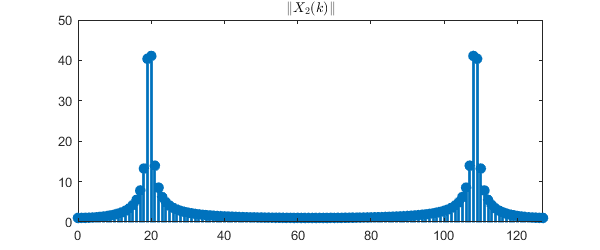

stem([0:127],abs(X2),'filled','LineWidth',2)
xlim([0 127])
title('$\|X_{2}(k)\|$','Interpreter','latex')

7. Utilice la función fft() de Matlab para calcular la transformada de Fourier discreta de 512 puntos de las secuencias 𝑥1(𝑛)=cos(40𝜋𝑛/128) y 𝑥2(𝑛)=𝑐𝑜𝑠(39𝜋𝑛/128). Utilice la función fftshift() para desplazar el componentecon frecuencia cero al centro del espectro y represente gráficamente el espectro de magnitud en el intervalo −𝜋≤𝜔<𝜋 utilizando la función plot().

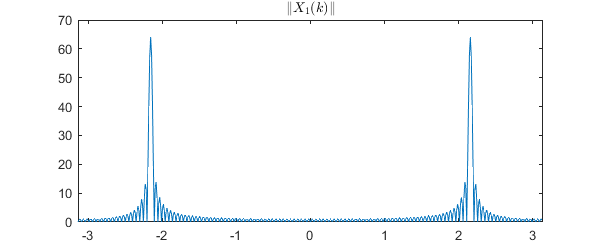

n = 0:127;
dw=2*pi/512;
w=-pi:dw:pi-dw;
x1 = cos(40*pi*n/128);
x2 = cos(39*pi*n/128);
X1 = fft(x1,512);
X2 = fft(x2,512);
X_1 = fftshift(X1,512);
X_2 = fftshift(X2,512);
plot(w,abs(X_1))
xlim([-pi pi])
title('$\|X_{1}(k)\|$','Interpreter','latex')

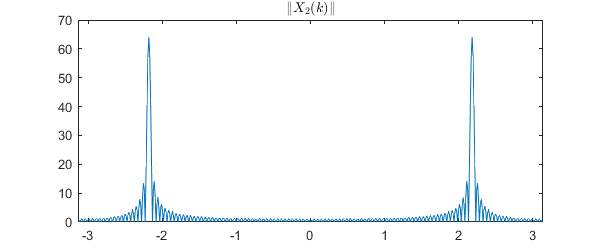

plot(w,abs(X_2))
xlim([-pi pi])
title('$\|X_{2}(k)\|$','Interpreter','latex')

Anexo

%Ejercicio 1

W4 = dftmtx(4);

W4 = sym(W4)

W8 = dftmtx(8);

W8 = sym(W8)

%Ejercicio 2

figure('Position',[500 400 600 250])

W4 = dftmtx(4);

x = [1;2;3;4];

X = W4*x;

stem([0:3],abs(X),'filled','LineWidth',2)  

title('$\|X(k)\|$','Interpreter','latex')

%Ejercicio 3

figure('Position',[500 400 600 250])

W8 = dftmtx(8);

x = [1;2;3;4;4;3;2;1];

X = W8*x;

stem([0:7],abs(X),'filled','LineWidth',2)  

title('$\|X(k)\|$','Interpreter','latex')

%Ejercicio 4

impulso = @(n) n==0;

n = 0:63;

x = impulso(n);

X = fft(x);

stem([0:63],X,'filled','LineWidth',2)

xlim([0 63])

title('$\|X(k)\|$','Interpreter','latex')

%Ejercicio 5

escalon = @(n) n>=0;

n = 0:7;

x = escalon(n)-escalon(n-8);

X = fft(x,128);

stem([0:127],abs(X),'filled','LineWidth',2)

xlim([0 127])

title('$\|X(k)\|$','Interpreter','latex')

%Ejercicio 6 

n = 0:127;

x1 = cos(40*pi*n/128);

x2 = cos(39*pi*n/128);

X1 = fft(x1);

X2 = fft(x2);

stem([0:127],abs(X1),'filled','LineWidth',2)

xlim([0 127])

title('$\|X_{1}(k)\|$','Interpreter','latex')

stem([0:127],abs(X2),'filled','LineWidth',2)

xlim([0 127])

title('$\|X_{2}(k)\|$','Interpreter','latex')

%Ejercicio 7

n = 0:127;

dw=2*pi/512;

w=-pi:dw:pi-dw;

x1 = cos(40*pi*n/128);

x2 = cos(39*pi*n/128);

X1 = fft(x1,512);

X2 = fft(x2,512);

X_1 = fftshift(X1,512);

X_2 = fftshift(X2,512);

plot(w,abs(X_1))

xlim([-pi pi])

title('$\|X_{1}(k)\|$','Interpreter','latex')

plot(w,abs(X_2))

xlim([-pi pi])

title('$\|X_{2}(k)\|$','Interpreter','latex')